# Neuron Clustering

1 - MapTmap raster 

2 - Uniform Manifold Approximation and Projection (UMAP)

% test with two clusters
c1 = 10*rand(1,100) + normrnd(0,1,20,100);
c2 = 10*rand(1,100) + normrnd(0,1,20,100);
ca=[c1;c2];
ops.iPC=1:30;
[sort1,~,~]=mapTmap(ca,ops);

Elapsed time is 0.457570 seconds.
Elapsed time is 0.686915 seconds.


 Running basic (ub) reduction, v1.5.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=30, n_components=2, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=false, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]


Elapsed time is 0.290425 seconds.
xattr: No such file: /Users/Elmi/Desktop/thesis_project/data/umapFileExchange (1/umap/mexStochasticGradientDescent.mexmaci64


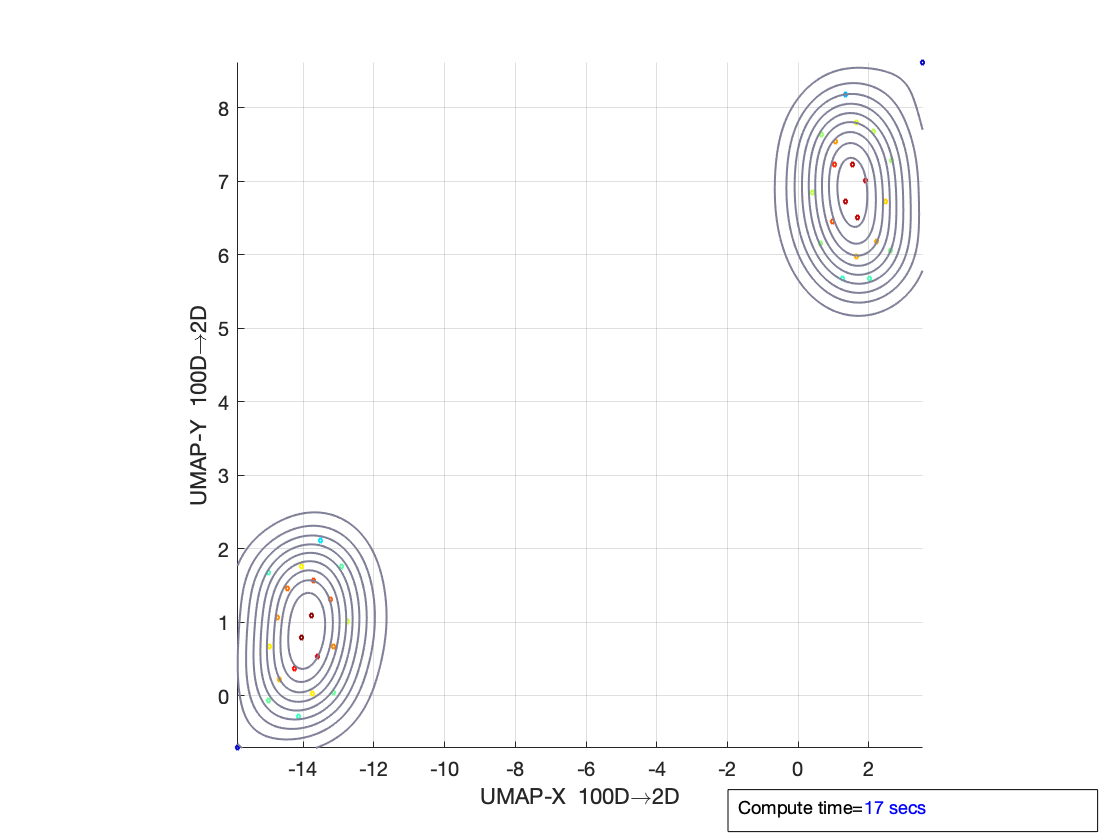

UMAP reduction finished (cost 17 secs)
 Finished basic (ub) reduction


[reduction, umap, clusterIdentifiers, extras]=run_umap(ca,'n_components',2);

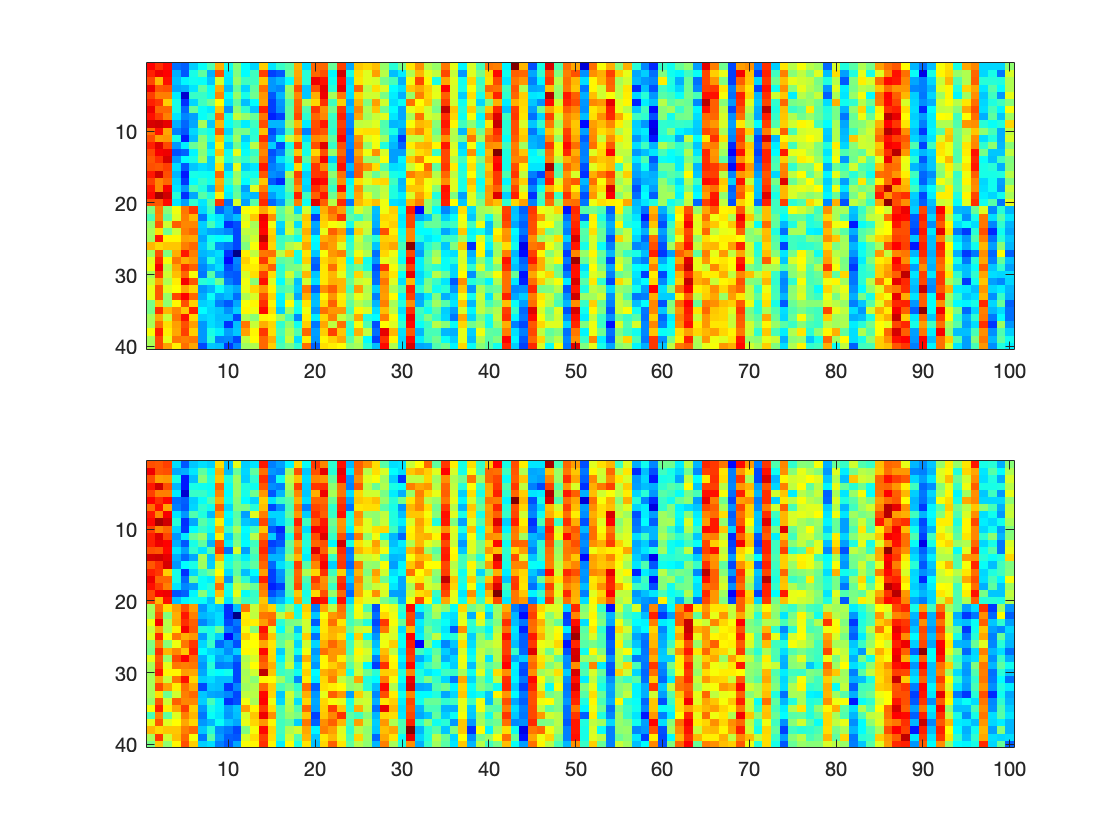

[~,idx]=sort(reduction(:,1),'descend');
subplot(2,1,1)
imagesc(ca(sort1,:))
subplot(2,1,2)
imagesc(ca(idx,:))

#### Sort signals 

Elapsed time is 1.576150 seconds.
Elapsed time is 1.862024 seconds.


 Running basic (ub) reduction, v1.5.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=10, n_components=2, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=false, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.053809 seconds.
xattr: No such file: /Users/Elmi/Desktop/thesis_project/data/umapFileExchange (1/umap/mexStochasticGradientDescent.mexmaci64


UMAP reduction finished (cost 15 secs)
 Finished basic (ub) reduction


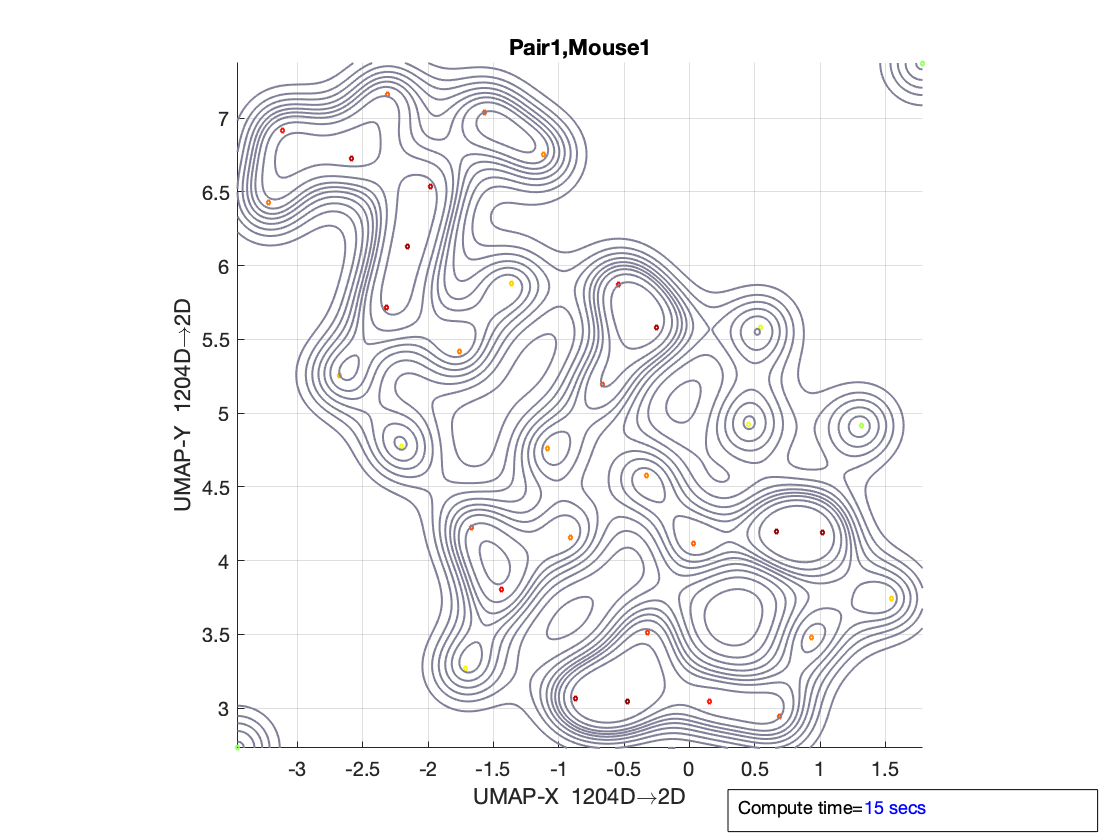

 Running basic (ub) reduction, v1.5.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=10, n_components=5, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=false, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.007043 seconds.
xattr: No such file: /Users/Elmi/Desktop/thesis_project/data/umapFileExchange (1/umap/mexStochasticGradientDescent.mexmaci64


UMAP reduction finished (cost 8 secs)
 Finished basic (ub) reduction


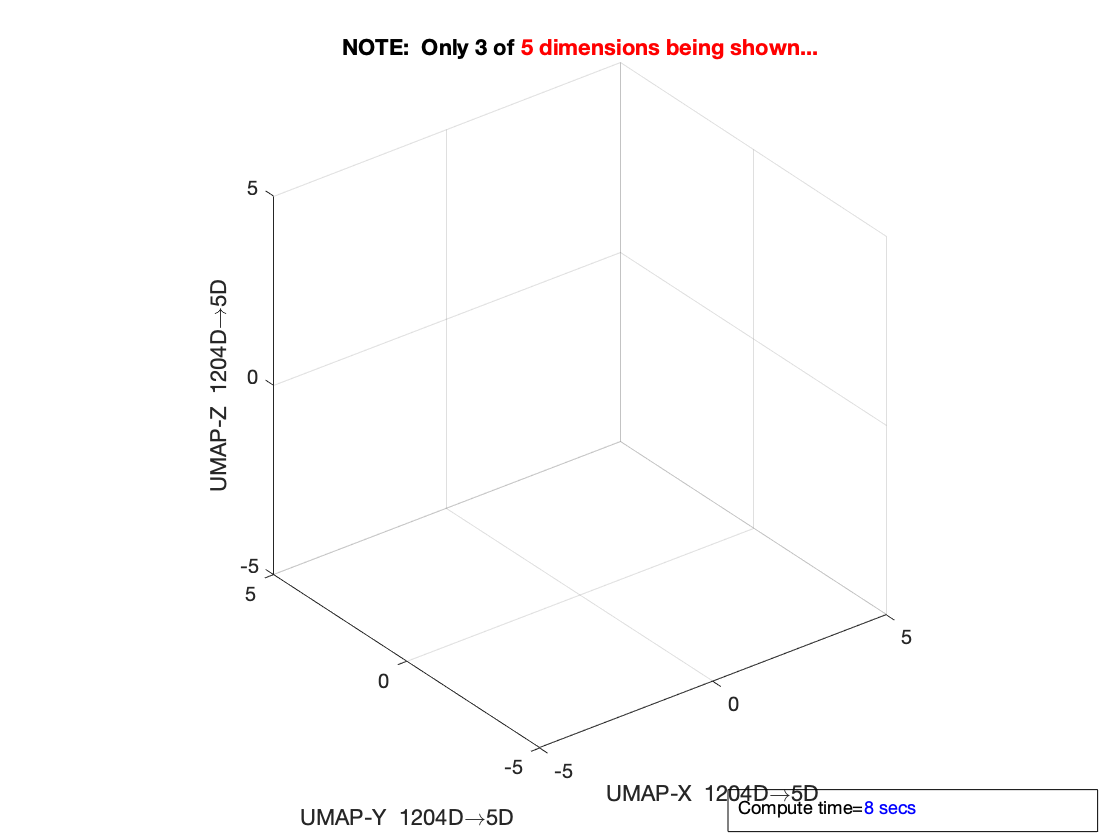

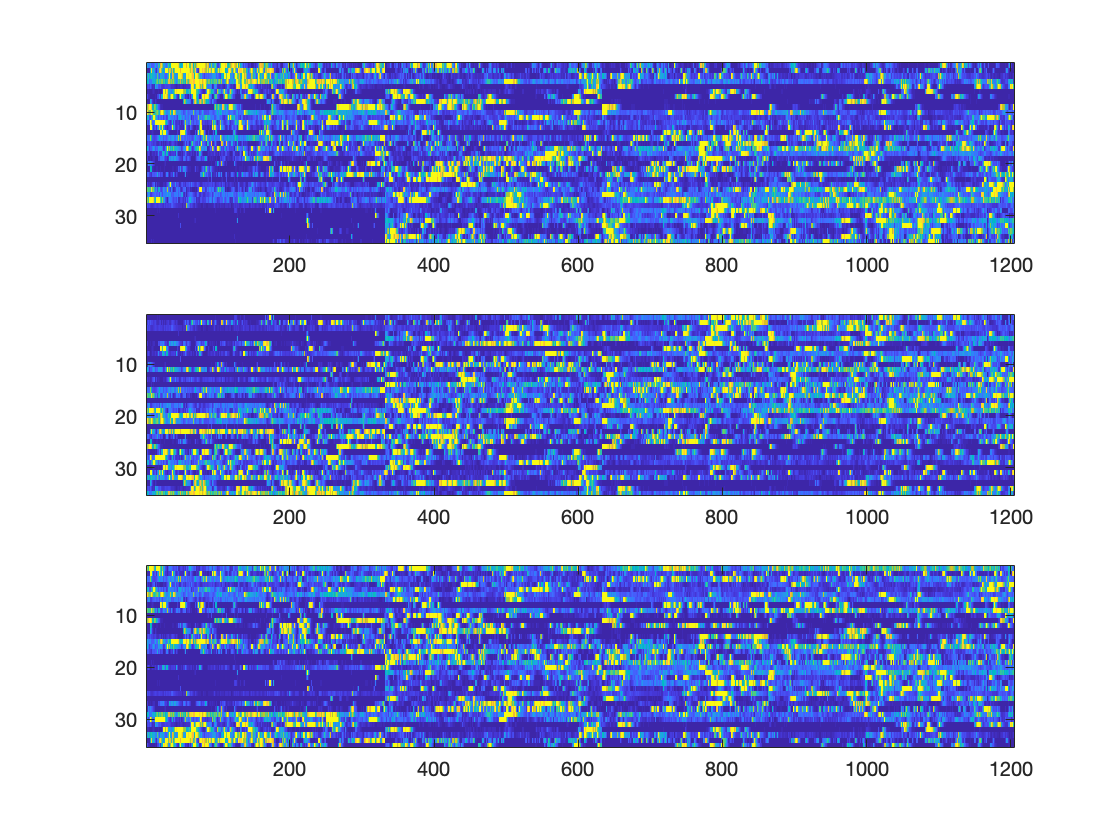

Elapsed time is 1.571668 seconds.
Elapsed time is 1.972109 seconds.


 Running basic (ub) reduction, v1.5.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=10, n_components=2, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=false, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.020802 seconds.
xattr: No such file: /Users/Elmi/Desktop/thesis_project/data/umapFileExchange (1/umap/mexStochasticGradientDescent.mexmaci64


UMAP reduction finished (cost 21 secs)
 Finished basic (ub) reduction


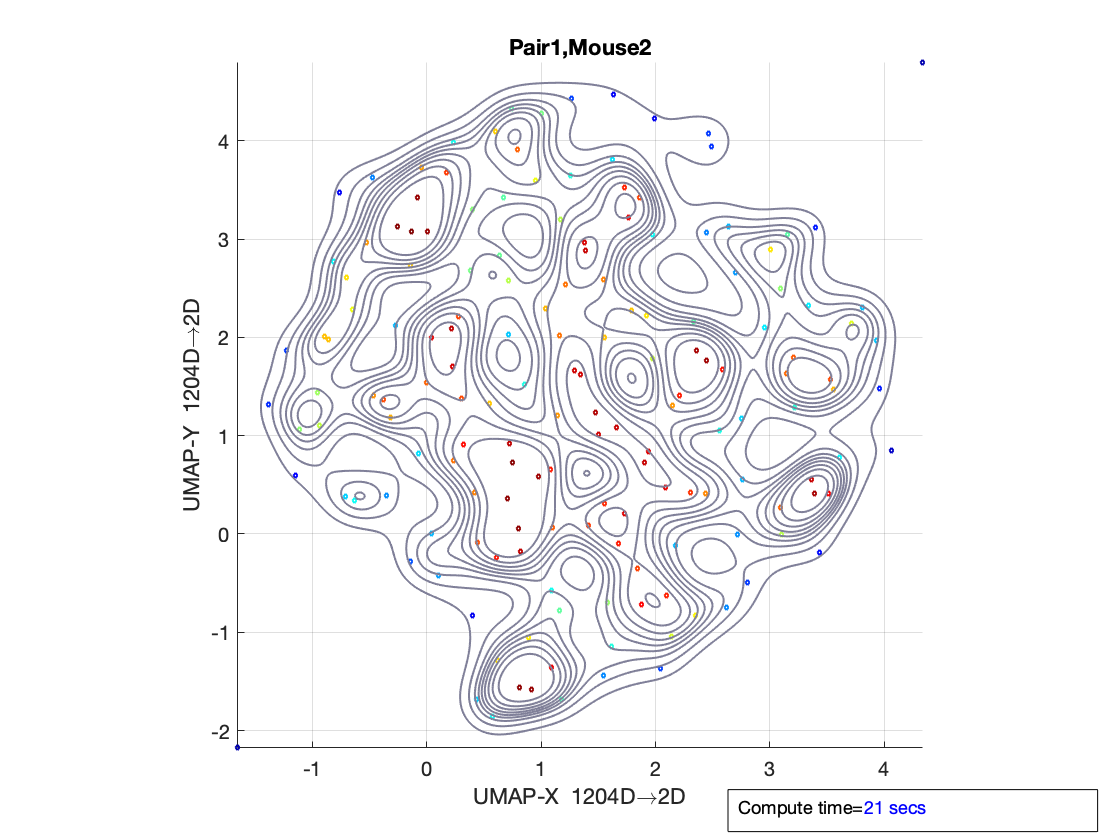

 Running basic (ub) reduction, v1.5.2
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=10, n_components=5, metric=euclidean, n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=false, metric_kwds=[], target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='euclidean', dist_args=[]
Elapsed time is 0.048120 seconds.
xattr: No such file: /Users/Elmi/Desktop/thesis_project/data/umapFileExchange (1/umap/mexStochasticGradientDescent.mexmaci64


UMAP reduction finished (cost 10 secs)
 Finished basic (ub) reduction


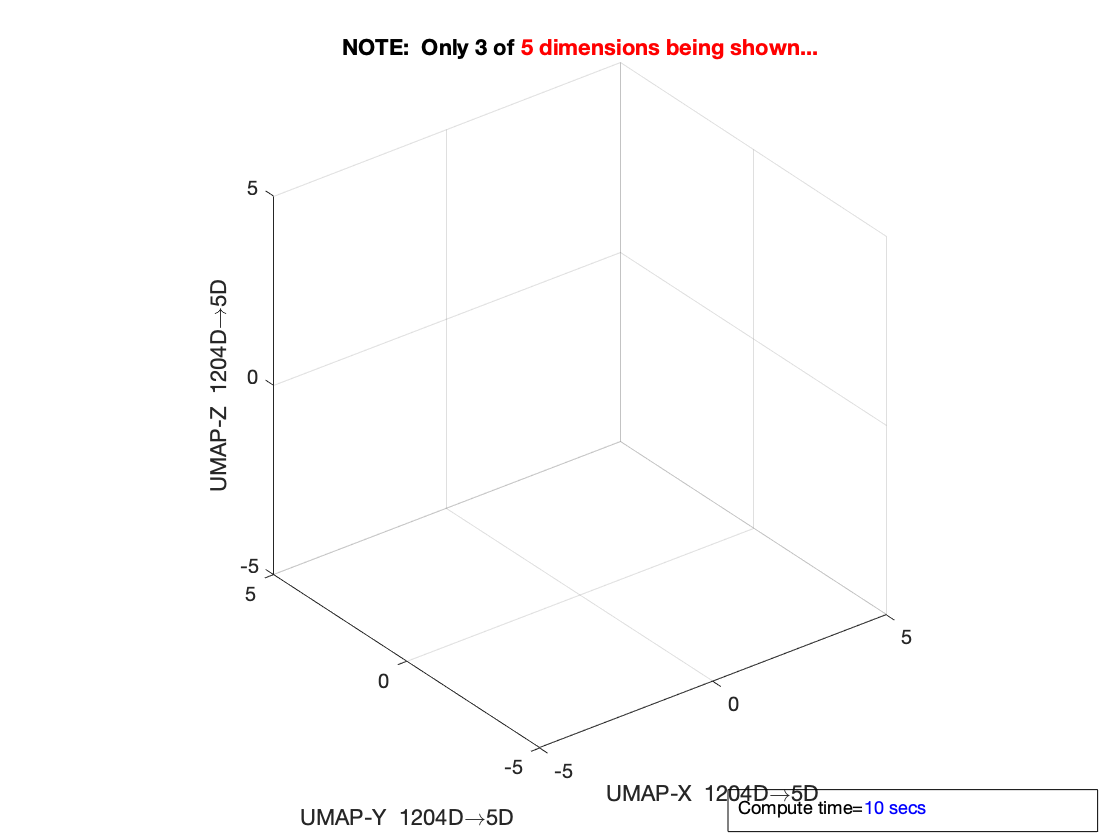

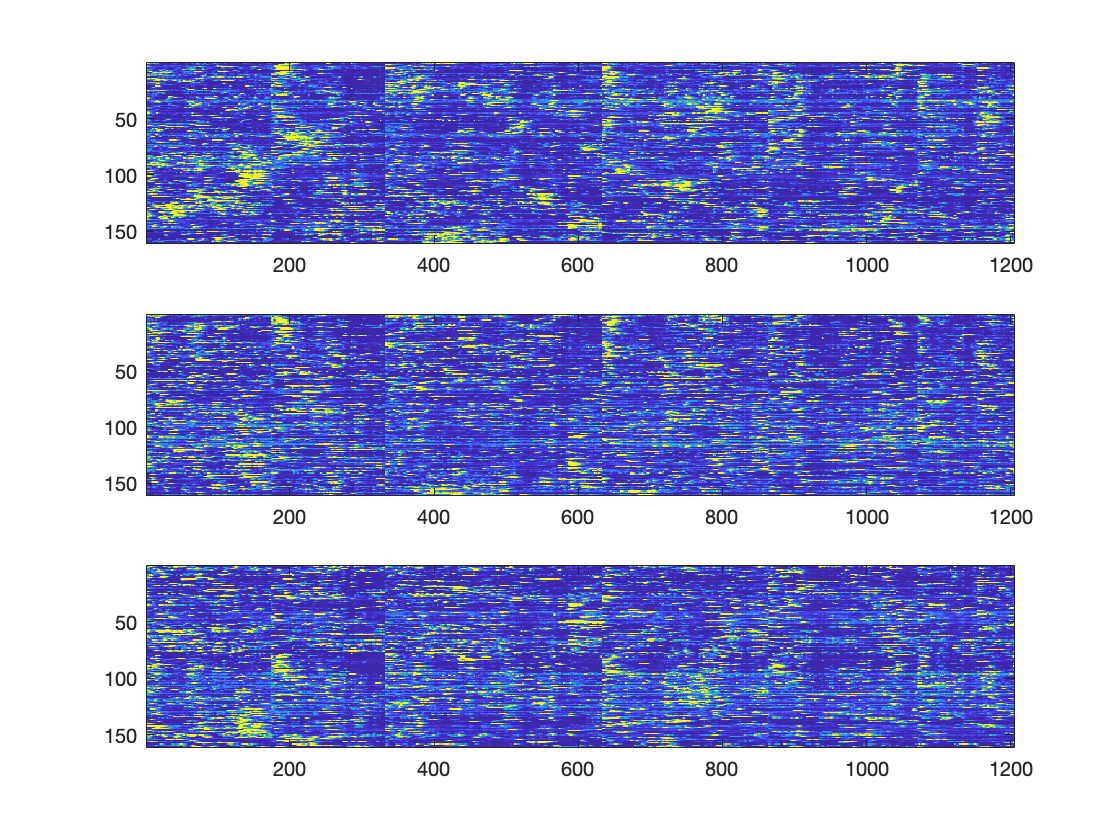

n=1;
minpts=[5,11];
for p=n
    for m=1:2
        ca=ca_cl{p,m};
        % mapTmap
        ops.iPC=1:30;
        [idx1,~,~]=mapTmap(ca,ops);
        % 2-dimension umap, visualization, direct sorting on 1 dimension
        figure
        [reduction, ~, clusterIdentifiers,~]=run_umap(ca, 'n_neighbors',10,'n_components',2);
        title(sprintf('Pair%d,Mouse%d',p,m))
        [~,idx2]=sort(reduction(:,1),'descend');
        % 5-dimension umap, sort by dbscan
        [reduction, ~, clusterIdentifiers,~]=run_umap(ca, 'n_neighbors',10,'n_components',5, 'cluster_output','none');
        xlim([-5 5]);ylim([-5 5]);zlim([-5 5]);
        idx3=dbscan(reduction,1,minpts(m));
        [~,idx3]=sort(idx3);
        figure
        subplot(3,1,1)
        imagesc(ca(idx1,:))
        subplot(3,1,2)
        imagesc(ca(idx2,:))
        subplot(3,1,3)
        imagesc(ca(idx3,:))
    end
end

- Overall mapTmap has better performance